# **Fiber section mesh generation**

**Here we demonstrate how to generate fiber cross sections using Matlab and OpenSees.**

**The **[Partial Differential Equation Toolbox - MATLAB](https://www.mathworks.com/products/pde.html)** is required.**

clear; clc;

opsmat = OpenSeesMatlab();
ops    = opsmat.opensees;
fs     = opsmat.pre.fiberSectionMesh; 
disp(fs);

  FiberSectionMesh with properties:

           parts: [1×1 struct]
          rebars: []
          secTag: NaN
      meshFibers: []
    sectionProps: []



### `EXAMPLE 1 — `Steel section

ops.wipe();
ops.model('basic', '-ndm', 3, '-ndf', 6);
% --- Material ---
ops.uniaxialMaterial('Steel02', 1, 345, 2.0e5, 0.01, 18, 0.925, 0.15);
% --- Geometry ---
ps = fs.IShape(200, 13, 374, 8);   % bf, tf, hw, tw — centred at origin

% --- Part (single material, no cover distinction needed) ---
parts(1).name     = 'Steel HN400';
parts(1).matTag   = 1;
parts(1).geometry = ps;
parts(1).meshSize = 20;            % fine mesh for steel (mm)

% --- Construct, mesh, inspect ---
sec1 = fs.new(parts, secTag=1);       % no rebars; secTag = 1
sec1.mesh();

Meshing complete: 146 fiber cells generated.


sec1.computeProps();
sectionProps = sec1.sectionProps;
sec1.printProps();


========== Cross-Section Properties ==========
  Total area         A     = 8192.0000
  Centroid           Cy    = 0.0000
                     Cz    = -0.0000
  2nd moment (horiz) Iy    = 229587479.4079
  2nd moment (vert)  Iz    = 17296957.8172
  Product of inertia Iyz   = 6713.8078
  Radius of gyration ry    = 167.4091
                     rz    = 45.9505
  Principal inertia  I1    = 229587479.6202
                     I2    = 17296957.6049
  Principal angle    theta = 89.9982  deg



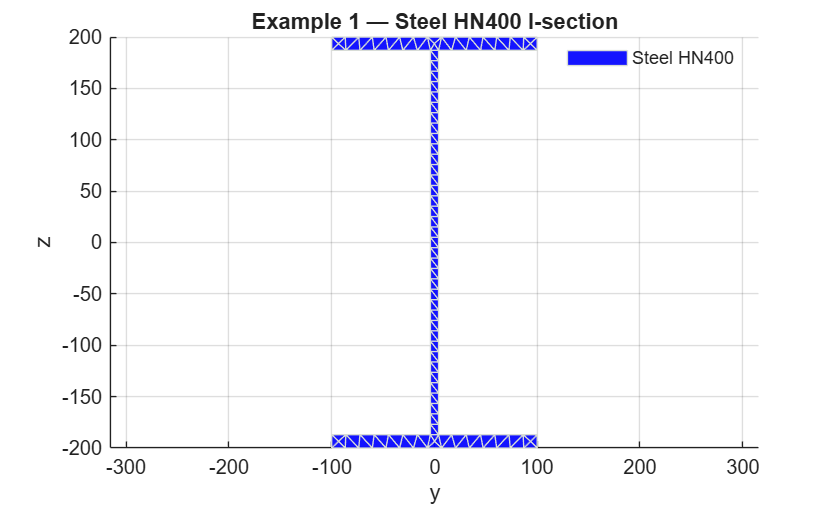

sec1.plot(fill=true);
title('Example 1 — Steel HN400 I-section');

% --- Write to OpenSees ---
opsmat.pre.setSectionGeometryRecorder(true);
sec1.build();  % Write to OpenSees domain

build: section Fiber 1 written to ops (146 solid fibers, GJ = 1e+12).


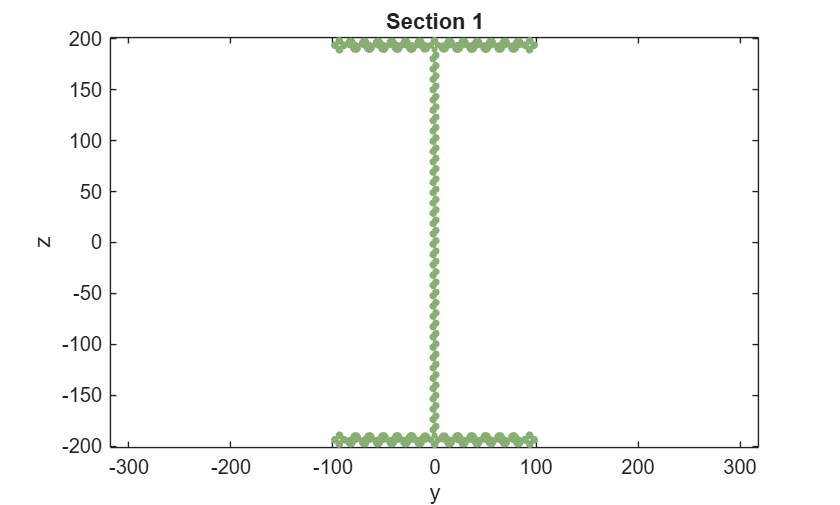

opsmat.pre.plotSection(1);

opsmat.pre.setSectionGeometryRecorder(false);

### `EXAMPLE 2 — RC box section`

`Matlab's geometric functions: `[Polygonal Shapes - MATLAB & Simulink](https://www.mathworks.com/help/matlab/elementary-polygons.html)

%% --- Materials ---
ops.wipe();
ops.model('basic', '-ndm', 3, '-ndf', 6);

ops.uniaxialMaterial('Concrete02', 2, -35, -0.005, -8.75, 0.02, 0.1, 2.0, 2000);
ops.uniaxialMaterial('Concrete02', 3, -30, -0.003, -6.0,  0.01, 0.1, 2.0, 2000);
ops.uniaxialMaterial('Steel02',    4, 400, 2.0e5, 0.01, 18, 0.925, 0.15);

%% --- Geometry: rectangular double-cell hollow box ---
% This example creates a double-cell hollow box section using MATLAB
% built-in polyshape operations. The section is divided into:
%   1) confined core concrete,
%   2) unconfined cover concrete,
%   3) longitudinal rebars placed along offset boundary paths.

% Overall section dimensions.
B = 2400;     % Total section width in the y-direction
H = 1600;     % Total section height in the z-direction

% Void dimensions and locations.
voidB  = 800;     % Width of each rectangular void
voidH  = 1100;    % Height of each rectangular void
voidCy = 600;     % Distance from section center to each void center

% Rebar layout parameters.
barGap = 180;     % Target spacing of rebars along each boundary path
rebarR = 12.5;    % Rebar radius, e.g., D25 bar

% Cover and mesh parameters.
coverThick = 40;                 % Clear concrete cover thickness
barCover   = coverThick + rebarR; % Distance from concrete face to rebar center
meshSize   = 80;                 % Target mesh size for triangular meshing

% Create the outer rectangular boundary.
outerPoly = polyshape( ...
    [-B/2, B/2, B/2, -B/2], ...
    [-H/2, -H/2, H/2, H/2]);

% Create the left rectangular void.
void1 = polyshape( ...
    [-voidCy-voidB/2, -voidCy+voidB/2, -voidCy+voidB/2, -voidCy-voidB/2], ...
    [-voidH/2, -voidH/2, voidH/2, voidH/2]);

% Create the right rectangular void.
void2 = polyshape( ...
    [ voidCy-voidB/2,  voidCy+voidB/2,  voidCy+voidB/2,  voidCy-voidB/2], ...
    [-voidH/2, -voidH/2, voidH/2, voidH/2]);

% Combine the two voids into one polyshape object.
voids = union([void1; void2]);

% Concrete wall region = outer box minus the two voids.
wallRegion = subtract(outerPoly, voids);

% Offset the outer boundary inward by coverThick.
% This defines the inner limit of the outer cover layer.
outerCoreLimit = polybuffer(outerPoly, -coverThick, 'JointType', 'miter');

% Offset each void boundary outward by coverThick.
% These regions represent the cover concrete around the inner void faces.
voidCover1 = polybuffer(void1, coverThick, 'JointType', 'miter');
voidCover2 = polybuffer(void2, coverThick, 'JointType', 'miter');
voidCovers = union([voidCover1; voidCover2]);

% Confined core = wall concrete inside the outer core limit,
% excluding the cover zones around the void boundaries.
coreRegion = intersect(wallRegion, outerCoreLimit);
coreRegion = subtract(coreRegion, voidCovers);

% Unconfined cover = remaining concrete outside the confined core.
coverRegion = subtract(wallRegion, coreRegion);

%% --- Parts ---
% Each part is assigned an OpenSees material tag and an independent mesh size.
clear parts

parts(1).name     = 'Confined core';
parts(1).matTag   = 2;
parts(1).geometry = coreRegion;
parts(1).meshSize = meshSize+10;   % slightly coarser mesh for core concrete

parts(2).name     = 'Unconfined cover';
parts(2).matTag   = 3;
parts(2).geometry = coverRegion;
parts(2).meshSize = meshSize;        % finer mesh for cover regions

%% --- Rebars using offset boundary + lineRebars ---
% Rebar centerlines are generated by offsetting concrete boundaries.
% The offset distance is coverThick + rebar radius, so that the clear cover
% from concrete face to rebar surface is approximately coverThick.

% Outer rebar path: offset the outer boundary inward.
outerBarPath = polybuffer(outerPoly, -barCover, 'JointType', 'miter');

% Inner rebar paths: offset void boundaries outward into the concrete walls.
innerBarPath1 = polybuffer(void1, barCover, 'JointType', 'miter');
innerBarPath2 = polybuffer(void2, barCover, 'JointType', 'miter');

% Extract boundary vertices from the offset paths.
[yOuter, zOuter] = boundary(outerBarPath);
[yIn1, zIn1] = boundary(innerBarPath1);
[yIn2, zIn2] = boundary(innerBarPath2);

% Generate rebar coordinates along each closed path.
% lineRebars guarantees that all path vertices are occupied by rebars and
% inserts additional bars along each segment according to the target gap.
outerBars  = fs.lineRebars(yOuter, zOuter, gap=barGap, closed=true);
innerBars1 = fs.lineRebars(yIn1, zIn1, gap=barGap, closed=true);
innerBars2 = fs.lineRebars(yIn2, zIn2, gap=barGap, closed=true);

% Merge all bar coordinates and remove duplicates at overlapping vertices.
allBarCoords = unique([outerBars; innerBars1; innerBars2], 'rows');

clear rebars
rebars(1).name   = 'HRB400 D25';
rebars(1).matTag = 4;
rebars(1).coords = allBarCoords;
rebars(1).area   = pi * rebarR^2;

%% --- Construct, mesh, inspect ---
sec2 = fs.new(parts, rebars=rebars, secTag=2);
sec2.mesh();

Meshing complete: 1268 fiber cells generated.


sec2.computeProps();
sectionProps = sec2.sectionProps;
sec2.printProps();


========== Cross-Section Properties ==========
  Total area         A     = 2080000.0000
  Centroid           Cy    = -0.0000
                     Cz    = 0.0000
  2nd moment (horiz) Iy    = 641139454973.3724
  2nd moment (vert)  Iz    = 1115233182245.6404
  Product of inertia Iyz   = -31533.9437
  Radius of gyration ry    = 555.1938
                     rz    = 732.2362
  Principal inertia  I1    = 1115233182245.6423
                     I2    = 641139454973.3702
  Principal angle    theta = -0.0000  deg



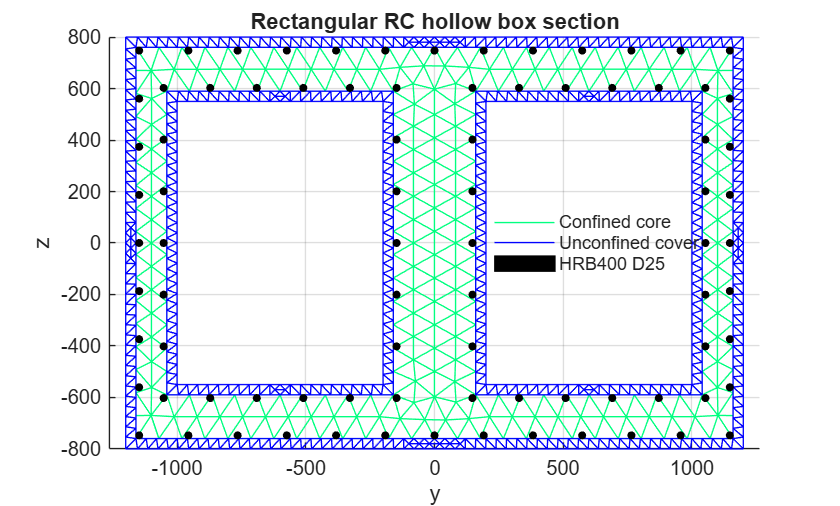

sec2.plot(fill=false);
title('Rectangular RC hollow box section');

%% --- Write to OpenSees domain ---
opsmat.pre.setSectionGeometryRecorder(true);
sec2.build();

build: section Fiber 2 written to ops (1268 solid fibers, 84 rebar fibers, GJ = 1e+12).


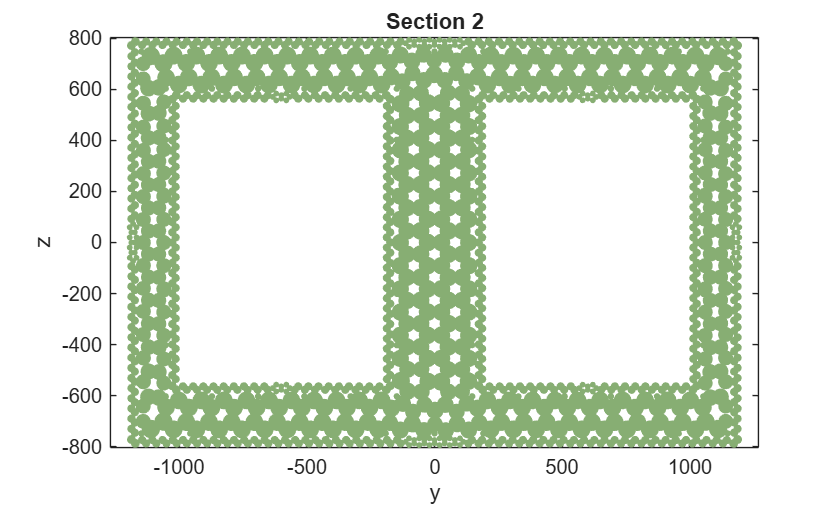

opsmat.pre.plotSection(2);

opsmat.pre.setSectionGeometryRecorder(false);